clc
clear all

imds=imageDatastore("foot_cancer_images\","IncludeSubfolders",true,"LabelSource","foldernames");
total_split= countEachLabel(imds)

total_split = 2×2 table
       Label       Count
    ___________    _____

    Diabetic        244 
    NonDiabetic      90 


num_images = length(imds.Labels)

num_images = 334

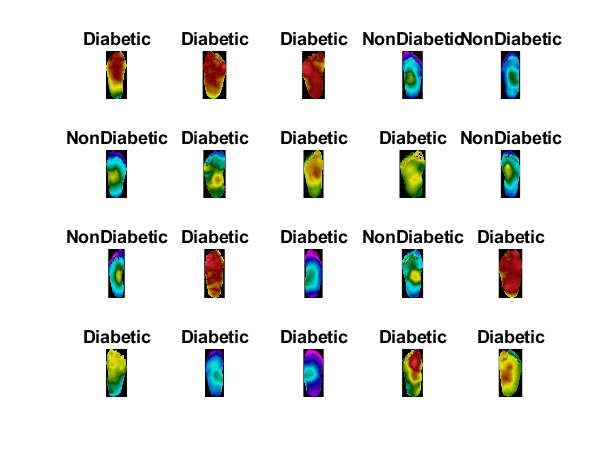



perm = randperm(num_images,20);
figure;
for idx=1:20
    subplot(4,5,idx);
    imshow(imread(imds.Files{perm(idx)}));
    title(sprintf('%s',imds.Labels(perm(idx))))
end


train_percent=0.80;
[imdsTrain,imdsTest]=splitEachLabel(imds,train_percent,'randomize');

valid_percent=0.1;
[imdsValid,imdsTrain]=splitEachLabel(imdsTrain,valid_percent,'randomize');

train_split=countEachLabel(imdsTrain)

train_split = 2×2 table
       Label       Count
    ___________    _____

    Diabetic        175 
    NonDiabetic      65 


valid_split=countEachLabel(imdsValid)

valid_split = 2×2 table
       Label       Count
    ___________    _____

    Diabetic        20  
    NonDiabetic      7  


test_split=countEachLabel(imdsTest)

test_split = 2×2 table
       Label       Count
    ___________    _____

    Diabetic        49  
    NonDiabetic     18  


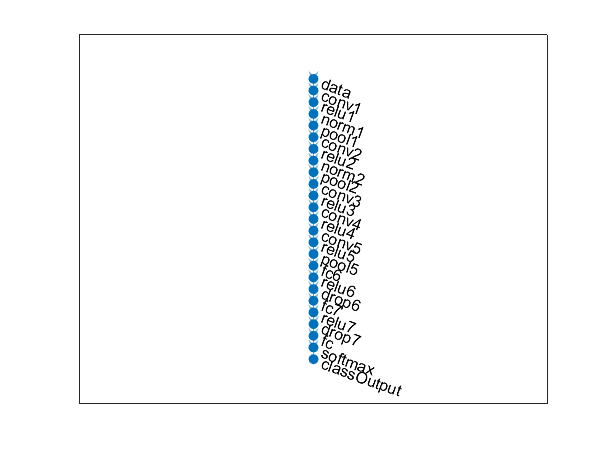


net=alexnet;
 
layersTransfer=net.Layers(1:end-3);
clear net;
numClasses=numel(categories(imdsTrain.Labels));

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'Name', 'fc','WeightLearnRateFactor',1,'BiasLearnRateFactor',1)
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classOutput')];
figure;
lgraph = layerGraph(layers);
plot(lgraph)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |       53.33% |       62.96% |       1.7510 |       0.6216 |      1.0000e-04 |
|       1 |           5 |       00:00:21 |       70.00% |       74.07% |       0.7797 |       0.7138 |      1.0000e-04 |
|       2 |          10 |       00:00:34 |       76.67% |       88.89% |       0.9162 |       0.2052 |      1.0000e-04 |
|       2 |          15 |       00:00:47 |       76.67% |       92.59% |       0.7096 |   

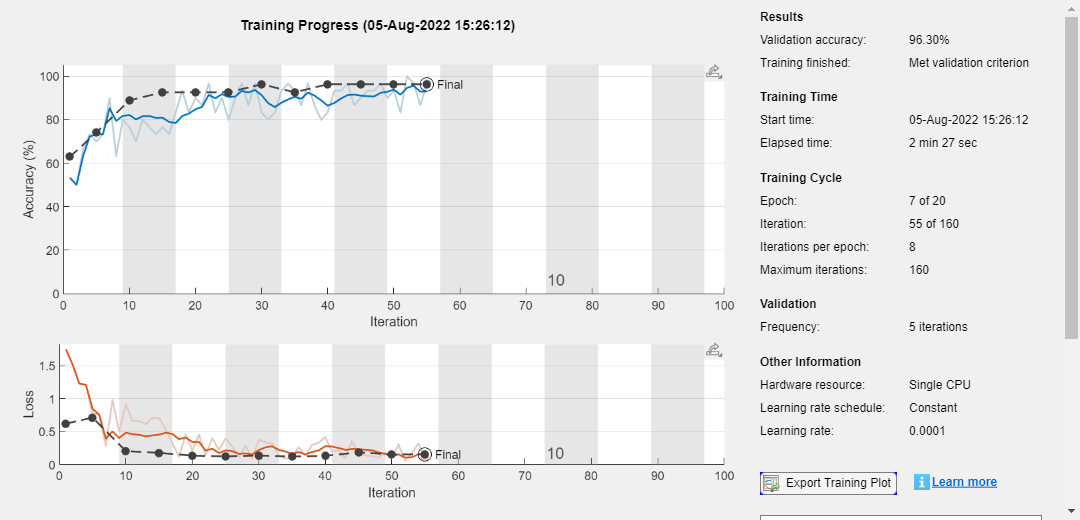


imageInputSize = layers(1).InputSize;
augmented_imdsTrain = augmentedImageDatastore(imageInputSize,imdsTrain);
augmented_imdsValid = augmentedImageDatastore(imageInputSize,imdsValid);

options=trainingOptions('sgdm', ...
    'MiniBatchSize',30, ...
    'MaxEpochs',20, ...
    'Shuffle','every-epoch', ...
    'InitialLearnRate',1e-4, ...
    'ValidationData',augmented_imdsValid, ...
    'ValidationFrequency',5,'ValidationPatience',4, ...
    'Plots','training-progress');

%Training
netTransfer=trainNetwork(augmented_imdsTrain,layers,options);

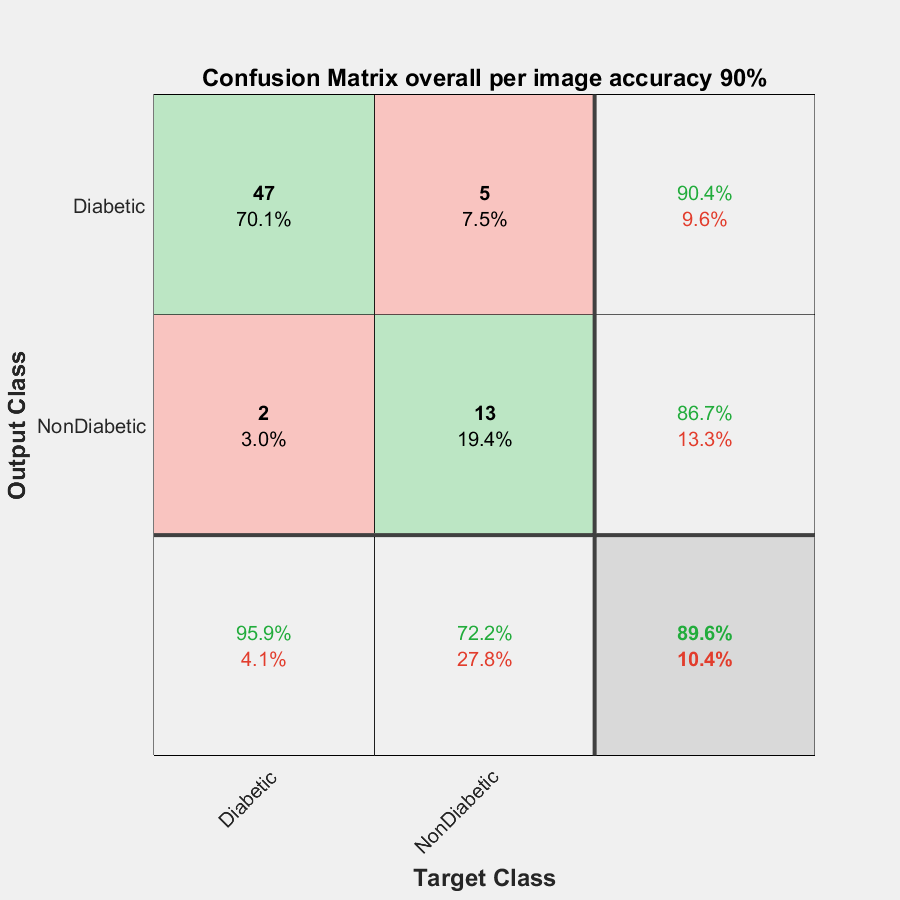

 
%Testing
augmented_imdsTest = augmentedImageDatastore(imageInputSize,imdsTest);
[predicted_labels,predicted_scores]=classify(netTransfer,augmented_imdsTest);

actual_labels=imdsTest.Labels;


figure;
plotconfusion(actual_labels,predicted_labels)
PerItemAccuracy = mean(predicted_labels == actual_labels);
title(['Confusion Matrix ','overall per image accuracy ',num2str(round(100*PerItemAccuracy)),'%'])